# This script is meant to guide you around the main commands and functions for your lab reports.

## 0: Getting the environment ready for work

Empty the workspace:

clear all

Empty the command window:

clc

## 1: Storing scalars

With **scalar** I mean a real number that does not need to be stored as an array, because it's one-dimensional. For instance, the speed of light, the distance betweeen two slits and the mass of an object can be regarded as scalars.

*Can you think of any other example?*

c = 3 * 10^8;            % m/s

slit_distance = 0.05;      % cm

mass = 8000;               % g

It is good practice to report the **unit of measure** of the stored scalars, as in a later step you'll need to convert them to SI units.

## 2: Storing experimental data into arrays

These are the quantities that you adjust or measure over the experiment and that will therefore take on different values as experimental  conditions change. Say applied voltage, applied pressure or applied temperature.

*Can you think of any other example?*

V = [100000, 105000, 110000, 115000, 120000];  % mV

p = [0.8, 0.9, 1.0, 1.1, 1.2];                 % bar

T = [-20, -10, 0, 10, 20];                     % °C

Experimental data is normally stored as an array of values. If you make more than one repeat to collect more data, then you might store the  repeats as different rows of the array:

angle_alpha = [45.0, - 61.3, 52.5, - 66.6, 89.8; 45.1, - 61.2, 52.4, - 66.5, 89.9];  % °

Here above, make sure you type ";" to suppress the result.

Mean of each column:

mean_angle_alpha = mean(angle_alpha);

## 3: Converting everything into SI units

Beware that if you skip this step, your results will look funny ;) First I convert the scalars and then the experimental data. You can either reassign stored variables or create new ones.

slit_distance = slit_distance / 100;        % cm to m

mass = mass / 1000;                         % g to kg

converted_V = V ./ 1000;                    % mV to V

converted_p = p .* 101325;                  % bar to Pa

converted_T = T + 273.15;                   % °C to K

## 4: Deriving secondary quantities from primary quantities

For this step you first need to think about what formula will be appropriate to apply. Say you know the distance between two slits and you measured the resulting angle (scalar slit_distance and array mean_angle_alpha, respectively).

*How do you get an array with the wavelenght values (lambda)?*

`formula: lambda * distance = m * sin(angle),  for m = 1`

lambda = slit_distance .* sin(mean_angle_alpha)  % m

lambda = 	1.0e+-3 *

    0.4380    0.5000    0.4088    0.2726    0.4755


Notice that the result is not a single number, but an entire array of values, as mean_angle_alpha is itself an array.

## 5: Evaluating uncertainties

You will soon receive an extended explanation on how to determine uncertainties. For now, you can look up what error propagation means and check out its formula.

Here I will evaluate the uncertainties we need so as to plot our errorbars in the next step, but you can go ahead to number 6.

angle_alpha_uncertainty(1:5) = 0.1;        % °

slit_distance_uncertainty = 0.005 / 100;    % cm to m

**Error propagation:**

lambda_uncertainty = slit_distance_uncertainty .* sqrt(sin(angle_alpha_uncertainty).^2 + (slit_distance_uncertainty .* cos(angle_alpha_uncertainty).^2))

lambda_uncertainty = 	1.0e+-5 *

    0.5004    0.5004    0.5004    0.5004    0.5004


## 6: Plotting data points and regression line

Now it's time to plot the results! If you are asked to include the uncertainties in your plot, you'll need to use the command "*errorbar()*", otherwise a straightdorward "*plot()*" will be enough.

`plot(x var, y var, 'ColorProperties')`

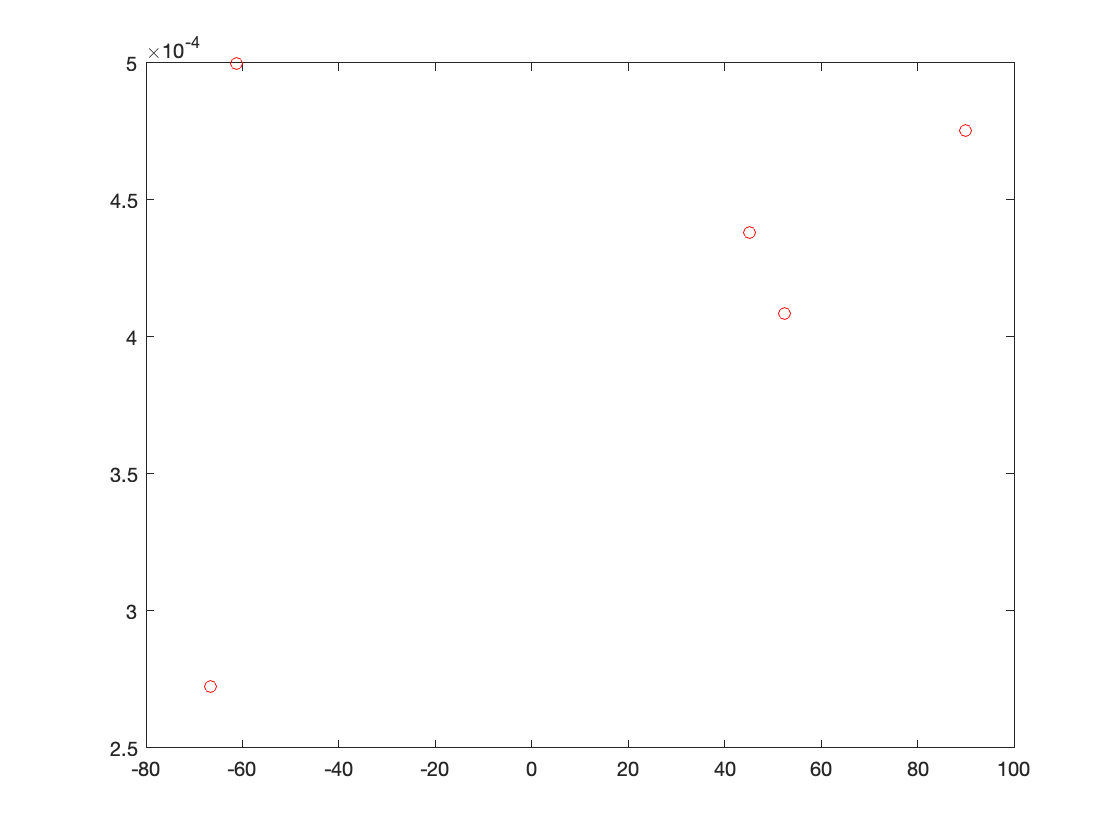

plot(mean_angle_alpha, lambda, 'ro')

`errorbar(x var, y var, unc. y var, unc. y var, unc. x var, unc. x var, 'ColorProperties')`

errorbar(mean_angle_alpha, lambda, lambda_uncertainty, lambda_uncertainty, angle_alpha_uncertainty, angle_alpha_uncertainty, 'ro')

Btw, the input 'ro' codes for "just points" as opposed to a line. We don'to want to draw a line because the command "fit()" will do the fitting job.

The fit command will determine the best fitting curve for the relationship between the two variables. Because the function we are investigating is lambda = d * sin(angle) or y = m * sin(x) + b, that is going to be the fitting function within the command.

`name = fit(transpose of x var, transpose of y var, 'FittingFunction')`

f = fit(mean_angle_alpha', lambda', 'm*sin(x)+b')

f =      General model:
     f(x) = m*sin(x)+b
     Coefficients (with 95% confidence bounds):
       b =   9.812e-09  (-1.002e-08, 2.965e-08)
       m =      0.0005  (0.0005, 0.0005)

- `'m*x+b': linear fit`

- `'Poly2': 2nd-degree polynomial`

- `Check out the documentation for other fit types.`

The output of the last line of code is really important: it will give you the uncertainties of the slope m and of the intercept b, so make sure you are NOT suppressing it with a ";".

Also remember to add f to your plot:

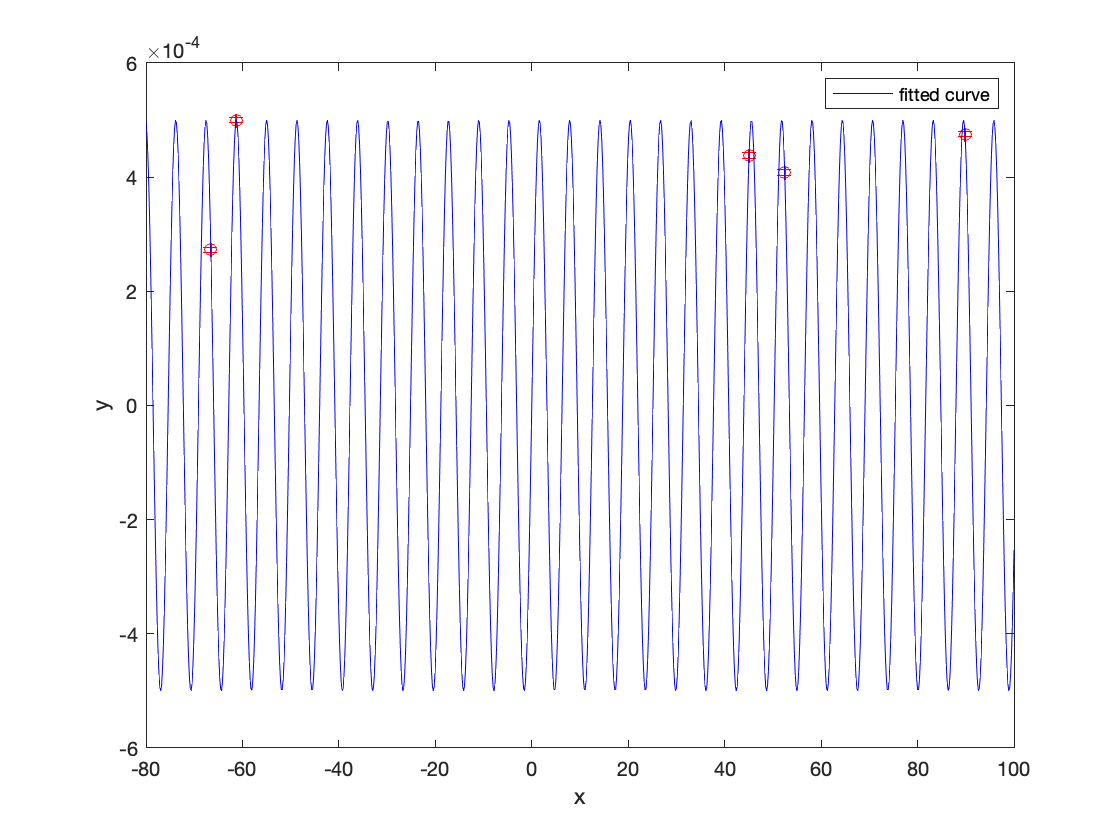

hold on
plot(f, 'b')

## 7: Decorating your plot

If we've come this far, you won't face any hardships from here on. Let's take a mental break and decorate our plot.

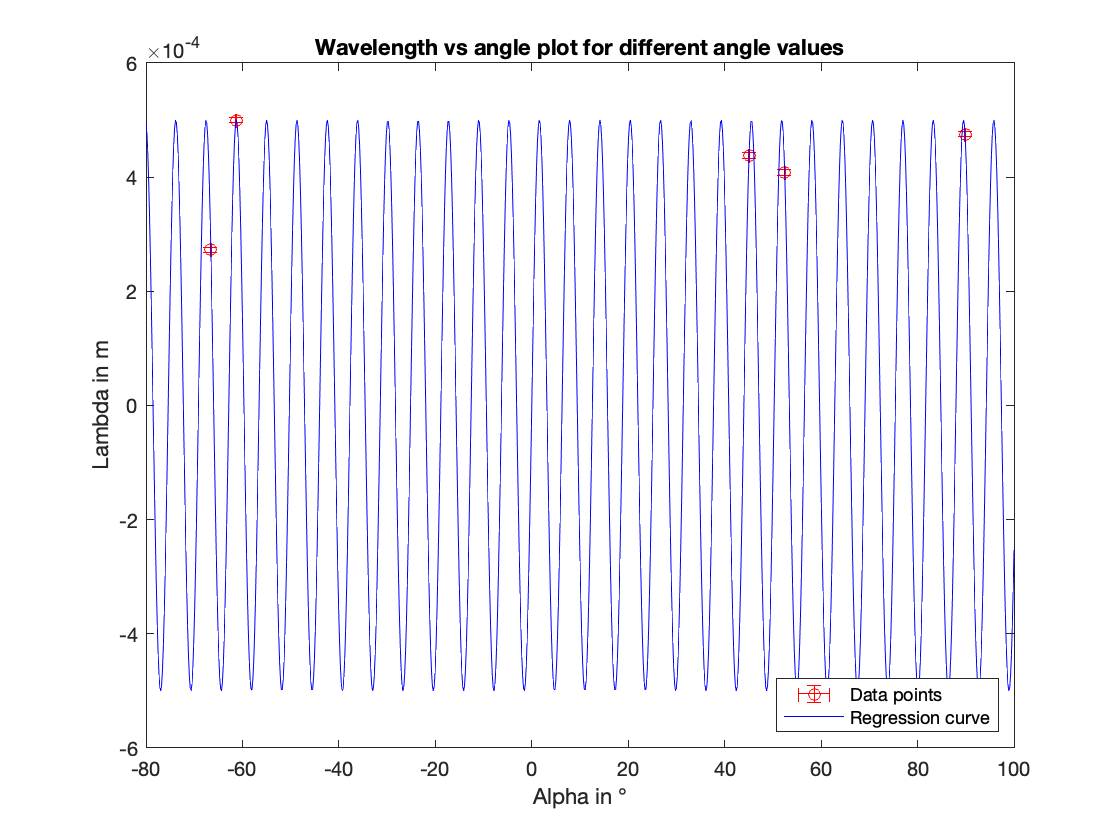

title('Wavelength vs angle plot for different angle values');
xlabel('Alpha in °');
ylabel('Lambda in m');
legend('Data points','Regression curve','Location','southeast');
hold off       

Congrats for getting this far. If you take home these steps, using MATLAB to write your lab reports might turn out to be a really nice adventure! Like all languages, the more you practice it, the better you'll get at it.

Take care!

Your student assistant Giulio